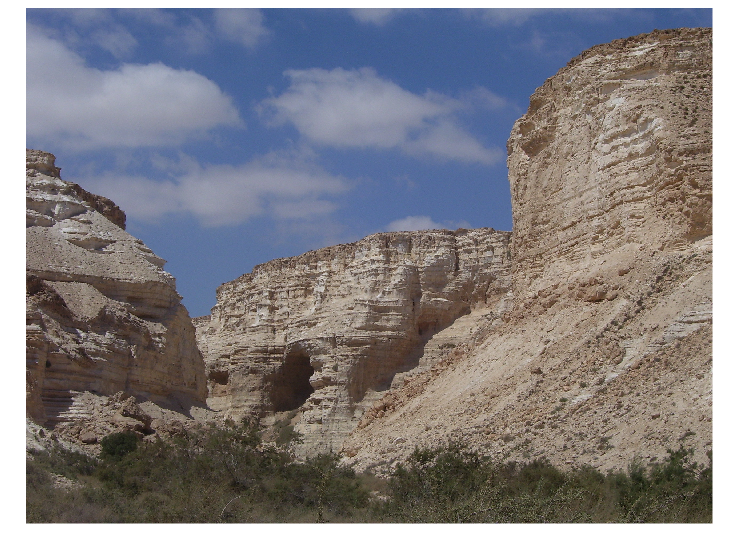

target = imread('dataset/natural_training/sun_aachaucttrrkdicr.jpg');
imshow(target);

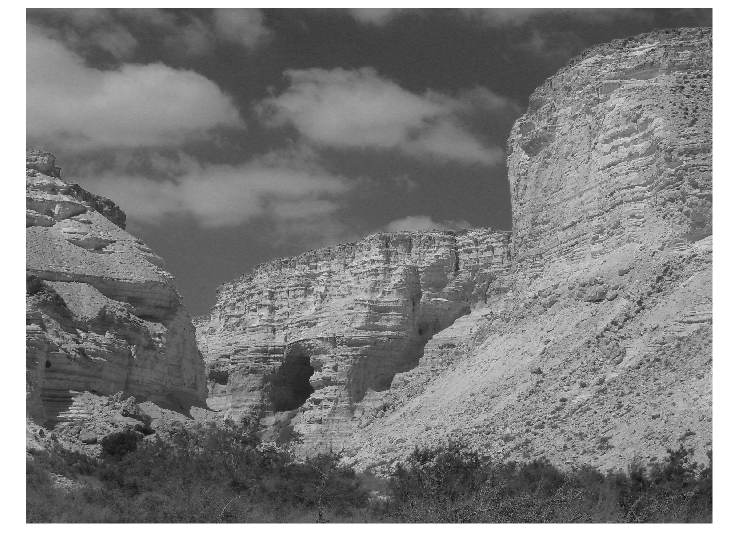

imshow(target(:,:,1));

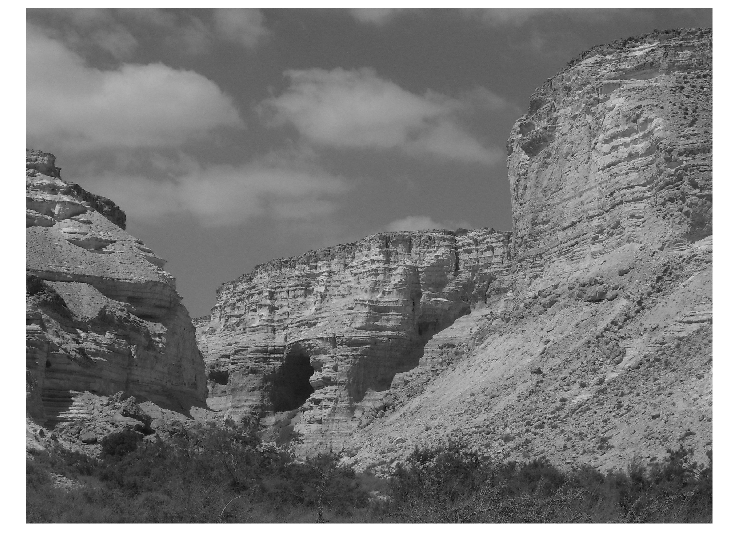

imshow(target(:,:,2));

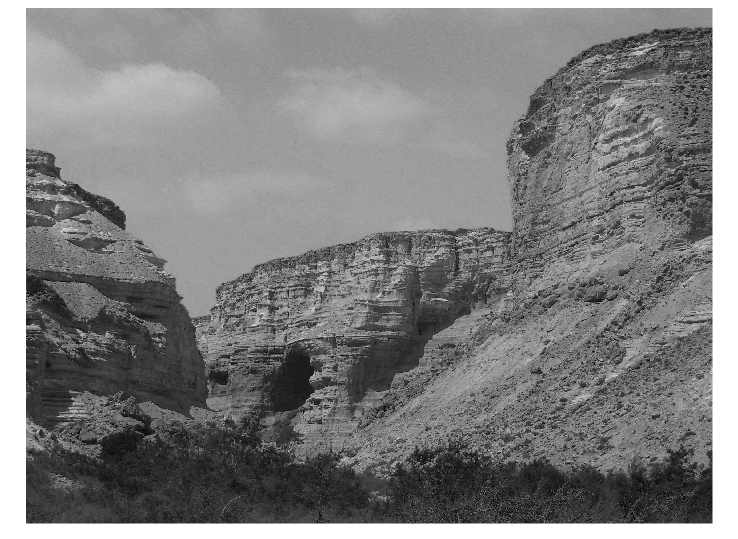

imshow(target(:,:,3));

h_target = GetHist(rgb2hsv(target));

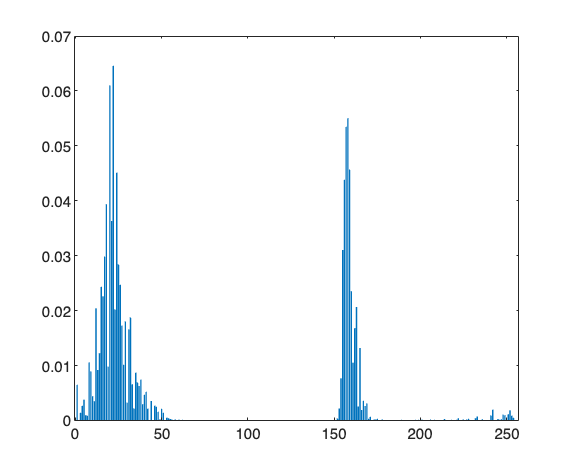

bar(h_target(:,1));

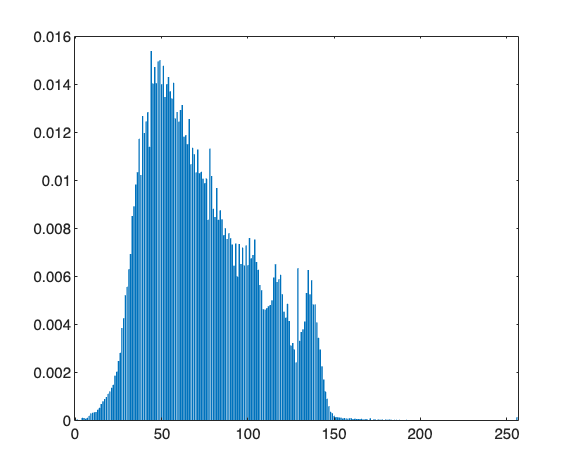

bar(h_target(:,2)); 

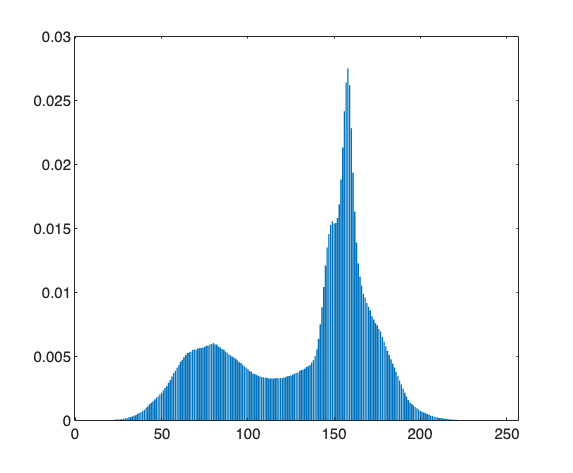

bar(h_target(:,3));

names = cell2mat(splitlines(fileread("dataset/natural_training.txt")));
names = strcat("dataset/", names);
num_names = size(names);

max_score = 0;
hist_score = zeros(num_names(1),1);
alpha = 0.5;
beta = 0.3;
for i = 1:num_names(1)
    name = names(i,:);
    source = rgb2hsv(imread(name));
    h_source = GetHist(source);
    score = [EuCompare(h_target(:,1), h_source(:,1)), EuCompare(h_target(:,2), h_source(:,2)),EuCompare(h_target(:,1), h_source(:,2))];
    mean_score = alpha * score(1) + beta * score(2) + (1 - alpha - beta) * score(3);
    hist_score(i,1) = mean_score;
end

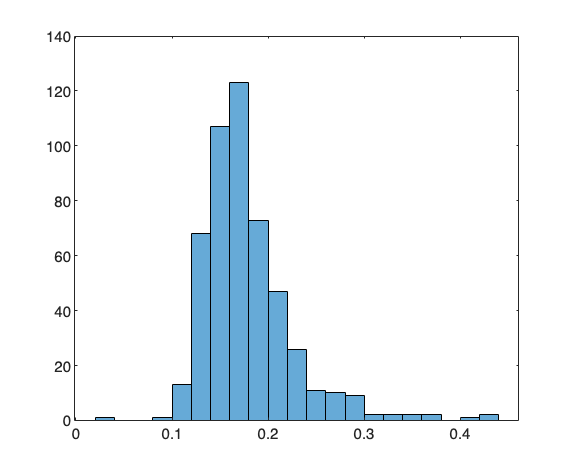

histogram(hist_score)

thold = 0.3;
matches = names(hist_score > thold);
scores = hist_score(hist_score > thold);
idx = randi([1, numel(matches)])

idx = 2

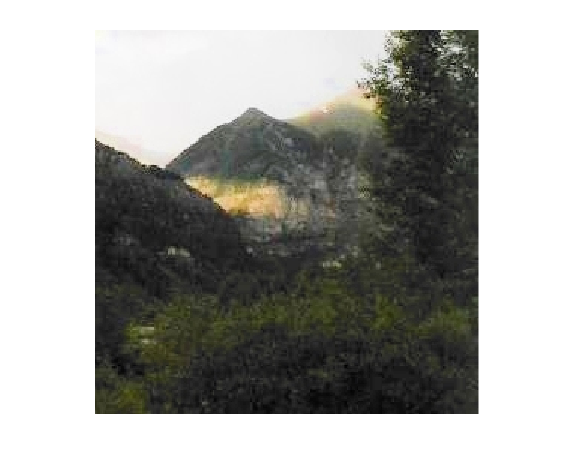

imshow(matches(idx));

scores(idx)

ans = 0.4223